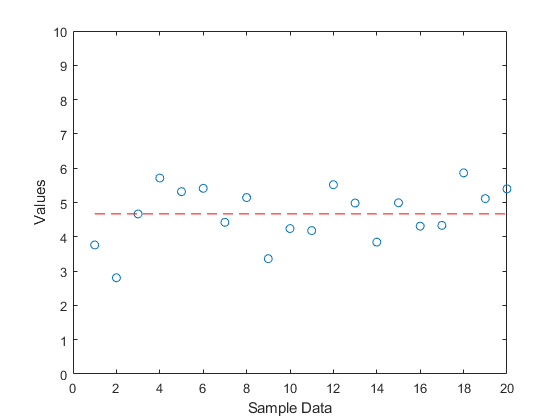

close all; %% close all the figure
clear; %% clear all the variable in workspace
clc; %% clear command screen
A = 5 + randn(20,1); %% add white noise
A_sum = sum(A);
A_avg = sum(A)/length(A);
plot(A,'o')
axis([0 20 0 10])
xlabel('Sample Data')
ylabel('Values')

%%draw the average line
A_avgV = A_avg*ones(length(A),1);
hold on;
plot(A_avgV,'r--')

A = randn(5,3)

A =     0.8840    0.4759   -0.5097
    0.1803    1.4122   -0.0029
    0.5509    0.0226    0.9199
    0.6830   -0.0479    0.1498
    1.1706    1.7013    1.4049


A_sum1 = sum(A) %%sum with the coulmn

A_sum1 =     3.4687    3.5642    1.9620


A_sum_vertical = sum(A,1) %%sum with the coulmn

A_sum_vertical =     3.4687    3.5642    1.9620


A_sum_horizontal = sum(A,2) %%sum with the row

A_sum_horizontal =     0.8501
    1.5896
    1.4933
    0.7849
    4.2769


A_sum2 = sum(A_sum1)

A_sum2 = 8.9949

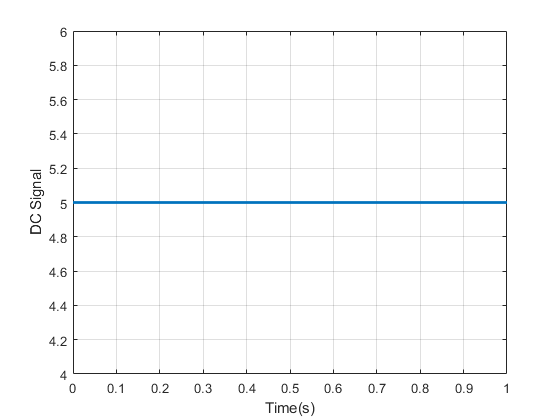

close all;
clc;
clear;
time = 0:0.001:1;

%%DC Signal
x_DC = 5.0*ones(1,length(time));
plot(time,x_DC,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("DC Signal")


%%Sinusodial signal
freq = 10

freq = 10

a = 2

a = 2

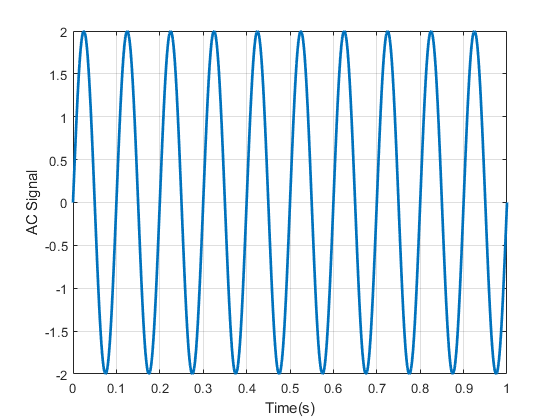

x_AC = a*sin(2*pi*freq*time);
figure
plot(time,x_AC,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("AC Signal")

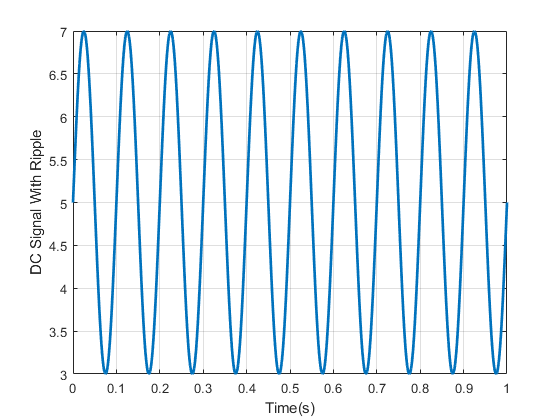


%%DC Signal with ripple
x_Ripple =x_DC + x_AC;
figure
plot(time,x_Ripple,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("DC Signal With Ripple")

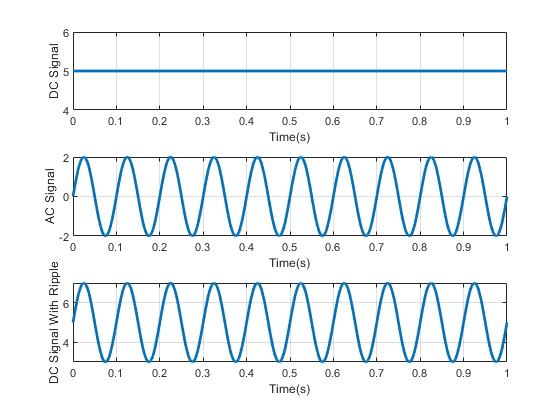


%%Put 3 figures together
figure
subplot(3,1,1)
plot(time,x_DC,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("DC Signal")

subplot(3,1,2)
plot(time,x_AC,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("AC Signal")

subplot(3,1,3)
plot(time,x_Ripple,"LineWidth",2)
grid on;
xlabel("Time(s)")
ylabel("DC Signal With Ripple")

A = [1 2 3]

A =      1     2     3


B = [4 5 6]

B =      4     5     6


A+B'  % inverse list

ans =      5     6     7
     6     7     8
     7     8     9


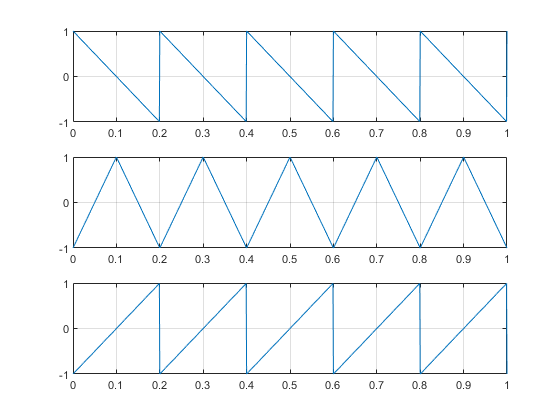

t = 0:0.001:1;
freq = 5;
x1 = sawtooth(2*pi*freq*t,0);
x2 = sawtooth(2*pi*freq*t,0.5);
x3 = sawtooth(2*pi*freq*t,1);

figure
subplot(3,1,1)
plot(t,x1);grid on;
subplot(3,1,2)
plot(t,x2);grid on;
subplot(3,1,3)
plot(t,x3);grid on;

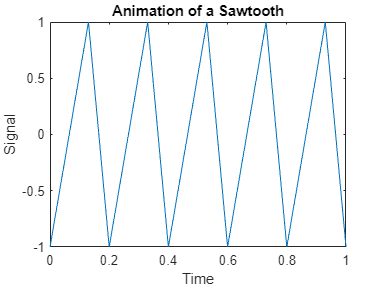

close all;
clc;
clear;

t = 0:0.001:1;
freq = 5;
x = sawtooth(2*pi*freq*t,0);

figure
HP = plot(t,x);
xlabel("Time");
ylabel("Signal");
title("Animation of a Sawtooth");

for ind = 1:20000
    for ratio = 0:0.005:1
        x = sawtooth(2*pi*freq*t,ratio);
        set(HP,"XData",t,"YData",x)
        drawnow;
    end
    for ratio = 1:-0.005:0
        x = sawtooth(2*pi*freq*t,ratio);
        set(HP,"XData",t,"YData",x)
        drawnow;
    end
end